# Greenhouse Model

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

In this script, you will design the control algorithm for a greenhouse. The system relies on a fan blowing fresh air from the outside to cool down the inside of the greenhouse during the warmer months of the year.

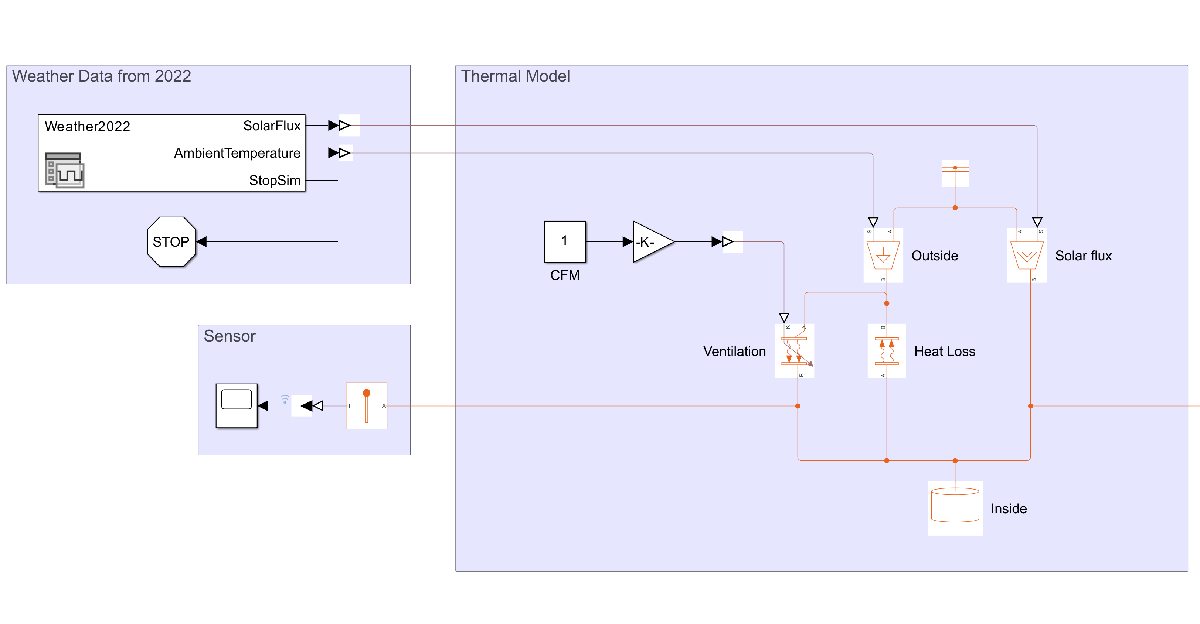

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

In [GreenhouseControl.mlx](matlab:open('./GreenhouseControl.mlx')), we developed the control algorithm for the greenhouse's fan. We could build a greenhouse prototype and verify that the fan effectively cools the greenhouse during the hottest summer days. However, building a prototype is expensive, and it would take days, weeks, or months to verify the system's efficiency. Therefore, we have decided to develop a model based design approach to study the ventilation's impact on the greenhouse's temperature.

## Model based design using Simscape

Simscape is a powerful physical modeling and simulation tool. It allows engineers to represent and simulate complex physical systems using a block diagram approach. Simscape enables the integration of physical simulation (electrical, mechanical, hydraulic, and other) into Simulink, providing a comprehensive platform for designing and analyzing dynamic systems.

### Building a Simscape model

In this script, we provide a Simscape model to simulate the temperature inside the greenhouse over a full year of data. The model relies on ambient air temperature and solar flux data gathered at a weather station in Natick, MA.

  **Try.** Open greenhouse' Simscape thermal model.

open(fullfile("InstructorResources","Solutions","GreenhousePlantSoln.slx"))
 

In the thermal model, the **Inside (Thermal Mass) **block represents the air's thermal mass inside the greenhouse. Its parameters include the total air mass in the greenhouse and the specific heat.

We detected an error in the formula for the total air mass contained in the greenhouse. The total mass should be defined as:


$$M_{t} = \rho V$$



$$V= HL^2$$


where $M_t$ is the total mass, $\rho$ is the density (`Density)`, $V$ is the greenhouse's volume, $H$ is the greenhouse's height (height`)`, and $L$ is the greenhouse's length (`Length`). The model workspace has been prepopulated with some parameters including:

- `Density `- the air density

- `Height` - the greenhouse's height

- `Length` - the greenhouse's length

Because these variable are declared in the model workspace, you can't see them in your MATLAB workspace, but they can be used in the model's blocks.

 **Exercise.** Double-click on the Inside block and correct the formula entered in the mass parameter.

 
CheckThermalMass

Now that the model is set correctly, you can simulate over a full year of data and visualize the temperature inside the greenhouse.

  **Try.** Simulate over a full year of data.

 
try
    SimOut = sim("GreenhousePlantSoln.slx");
    clear SimOut
    isReady = true;
catch ErrorMessage
    warning("The simulation could not run.")
    warning("This is because Simscape require a special solver attached to the physical domain (colored line).")
end

The Simscape solver is already included in the model and must only be connected to the physical domain to fix the error message encountered in the running stage.

 **Exercise.** Add a connection between the solver and the physical domain (colored line).

 
CheckSolver

Good job! You connected the solver correctly.


  **Try.** Simulate over a full year of data.

 
try
    tic
    SimOut = sim("GreenhousePlantSoln.slx");
    t = toc;
    disp("Good job! You simulated a full year in "+t+" seconds.")
    isReady = true;
catch ErrorMessage
    warning("The simulation could not run.")
    warning("This is because Simscape require a special solver attached to the physical domain (colored line).")
end

### Exploring Results

Now that you have managed to simulate the full year of data, we should look at the results from the simulation. In this part of the script, we are going to explore three ways to check the simulation results:

- Using Simscape Results Explorer

- Using scopes

- Using MATLAB

#### Using Simscape Results Explorer

Simscape provides a Results Explorer app with detailed results from the physical domain. 

  **Try.** Open Simscape Results Explorer using one of the following methods:

- In the model window, on the **Simulation** tab, click **Review Results** > **Simscape Results Explorer**.

- Using the `sscexplore` function by clicking the following button

 
if exist("SimOut","var") && exist("isReady","var")
    sscexplore(SimOut.simlog)
else
    warning("Please complete the previous section in order before to run this part.")
end

 **Exercise. **Plot the temperature of the greenhouse's air in **GreenhousePlant > Inside > T**, using the Simscape Results Explorer

#### Using scopes

The second way to explore the results from the simulation is to use sensors and scope blocks. Sensor blocks measure physical quantities such as temperature in your physical domain, and scope blocks allow you to plot these quantities. The scope and sensor required to visualize the system's temperature have already been included in your model, but they are commented out.

 **Exercise. ** Right-click on the block in the Sensor area to uncomment the block.

Tips: Uncomment the whole sensor area at once by selecting every block in the area.

 
CheckUncommentSensor

Good job! You uncommented the sensor blocks correctly.


The sensor is now included in the model but is not connected to the inside temperature signal.

 **Exercise. **Connect the sensor to the **Inside** temperature

 
if exist("isReady","var")
    load_system(fullfile("Models","GreenhousePlant"));
    InsideID = getSimulinkBlockHandle("GreenhousePlant/Inside");
    connectivities = get_param("GreenhousePlant/Temperature Sensor","PortConnectivity");
    isConnected = ~isempty(connectivities(1).DstBlock);
    isConnectedToInside = any(connectivities(1).DstBlock == InsideID);
    err = false;
    if ~isConnected
        err = true;
        warning("The sensor is not connected to the thermal model.")
    end
    if ~isConnectedToInside
        err = true;
        warning("The connection needs to be linked to the Inside block.")
    end
    if ~err
        disp("Good job! The sensor is connected to the thermal model correctly.")
    end
else
    warning("Please complete the previous section in order before to run this part.")
end

  **Try.** Double-click the scope and click the run button in the toolstrip.

#### In MATLAB

You might have noticed that the signal going into the scope is being logged 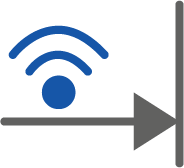. This allows us to transfer the signal data from Simulink to MATLAB and analyze the results.

  **Try. **Run the following code to plot the results.

 
if exist("isReady","var")
    % Run the simulation
    SimOut = sim("GreenhousePlantSoln.slx");
    
    % Retrieve the temperature
    SimOut = timeseries2timetable(SimOut.logsout{1}.Values);
    SimOut.Properties.VariableNames(1) = "Temperature (K)";
    
    % Set the date from January 1st 2022
    SimOut.Time = datetime("Jan 1, 2022") + SimOut.Time;
    
    % Plot temperature
    figure
    plot(SimOut,"Time","Temperature (K)")
else
    warning("Please complete the previous section in order before to run this part.")
end

The temperature plot is not smooth because of the daily variation of the temperature. 

 **Exercise. **Retime the **SimOut** timetable with a **time step of 1 day **using a general rule **Maximum, **the output timetable should be **SimOut**.

TimeStep = "yearly";
Method = "nearest";
 
if exist("isReady","var")
    SmoothSimOut = retime(SimOut,TimeStep,Method);
else
    warning("Please complete the previous section in order before to run this part.")

% Retime timetable
SimOut = retime(SimOut,"regular","max","TimeStep",caldays(3))

SimOut = 122×3 timetable
       Time        Temperature (K)    Temperature (F)    Temperature (C)
    ___________    _______________    _______________    _______________

    01-Jan-2022        290.67             63.536              17.52     
    04-Jan-2022        290.55             63.317             17.398     
    07-Jan-2022        286.71             56.401             13.556     
    10-Jan-2022        285.94             55.015             12.786     
    13-Jan-2022         289.9             62.149              16.75     
    16-Jan-2022        289.65             61.702             16.501     
    19-Jan-2022        288.98             60.493             15.829     
    22-Jan-2022        283.56             50.

end
% Plot temperature
if exist("SmoothSimOut","var")
    figure
    plot(SmoothSimOut,"Time","Temperature (K)")
else
    warning("Please complete the previous section in order before to run this part.")
end

The temperature output from the thermal model is in Kelvin. This might not be your preferred unit of temperature. You could convert the temperature from Kelvin to Fahrenheit and Celsius using the following relation:


$$T(^\circ F) = a_1 T(K) + b_1 \\
T(^\circ F) = a_2 T(K) + b_2 \\$$


A quick online search will give you the value for the coefficient $a_{1,2}$ and $b_{1,2}$.

 **Exercise. **Adjust the $a_1$ and $b_1$ values to create the Fahrenheit temperature from the Kelvin temperature.

if exist("SmoothSimOut","var")
    a = [ ];
    b = [ ];
     

    err = false;
    if isempty(a)
        warning("Please enter a value for a.")
        err = true;
    else
        if a < 1.81 && a > 1.79
        else
        warning("The value for a is wrong.")
        err = true;
        end
    end

    if isempty(b)
        warning("Please enter a value for a.")
        err = true;
    else
        if b < 461 && b > 458
        else
        warning("The value for b is wrong.")
        err = true;
        end
    end

    if ~err
        SmoothSimOut.("Temperature (F)") = a*SmoothSimOut.("Temperature (K)")+b;
    end

else
    warning("Please complete the previous section in order before to run this part.")
end

 **Exercise. **Adjust the $a_2$ and $b_2$ values to create the Celsius temperature from the Kelvin temperature.

if exist("SmoothSimOut","var")
a = 1;
b = -273.15;
     

    err = false;
    if isempty(a)
        warning("Please enter a value for a.")
        err = true;
    elseif a == 1
    else
        warning("The value for a is wrong.")
        err = true;
    end

    if isempty(b)
        warning("Please enter a value for a.")
        err = true;
    elseif b < 274 && b > 273
    else
        warning("The value for b is wrong.")
        err = true;
    end

    if ~err
        SmoothSimOut.("Temperature (C)") = a*SmoothSimOut.("Temperature (K)")+b;
    end
else
    warning("Please complete the previous section in order before to run this part.")
end

  **Try.** Plot the results in Fahrenheit

select = "Temperature (K)";
if exist("SimOut","var") && exist("isReady","var")
    if any(string(SmoothSimOut.Properties.VariableNames) == select)
        figure
        plot(SmoothSimOut,"Time",select)
    else
        warning("The field "+select+" has not been create in the table yet. Rerun the previous interaction")
    end
else
    warning("Please complete the previous section in order before to run this part.")
end

## Testing the design

At this point, we have implemented a thermal model to simulate the behavior of the greenhouse over a full year. It has a fan that constantly extracts 1 CFM (cubic feet per minute) of air from the greenhouse. In [GreenhouseControl.mlx](matlab:open('./GreenhouseControl.mlx')), we designed a control algorithm for the fan that depends on the current temperature in the greenhouse.

### Adding the control algorithm

We prepare the same thermal model by adding the control algorithm from [GreenhouseControl.mlx](matlab:open('./GreenhouseControl.mlx')). 

  **Try.** Open the new model.

open(fullfile("InstructorResources","Solutions","GreenhousePlantWithControlSoln.slx"))
fullfile("InstructorResources/Solutions/GreenhousePlant")

ans = "InstructorResources\Solutions\GreenhousePlant"

  **Try.** Run the simulation and observe the Stateflow Chart. It should indicate when the fan is on or off.

sim(fullfile("InstructorResources","Solutions","GreenhousePlantWithControlSoln.slx"));
 

### Testing multiple fan

We now have a complete model that can be used to study the effect of the fan on the greenhouse's temperature. We are now trying to define and determine the fan size necessary to maintain a temperature below 90F year long.

We are characterizing the size of the fan by its CFM value, the number of cubic feet per minute it can extract from the greenhouse.

 **Exercise. **Define the experiment plan by selecting the number of fans you would like to test, the minimum CFM, and the maximum CFM.

minCFM = 1;
maxCFM = 1000;
numFan = 5;
CFM = round(logspace(log10(minCFM),log10(maxCFM),numFan));
 
CheckExperimentPlan(minCFM,maxCFM,numFan);

Good job! You define a reasonable experiment plan.


Now that you have defined your experiment plan, we can use the same model used previously to test every fan.

  **Try.** Click the **Run All Simulations **button to test every fans. Each line represents the temperature with a different fan; their CFM is included in the legend.

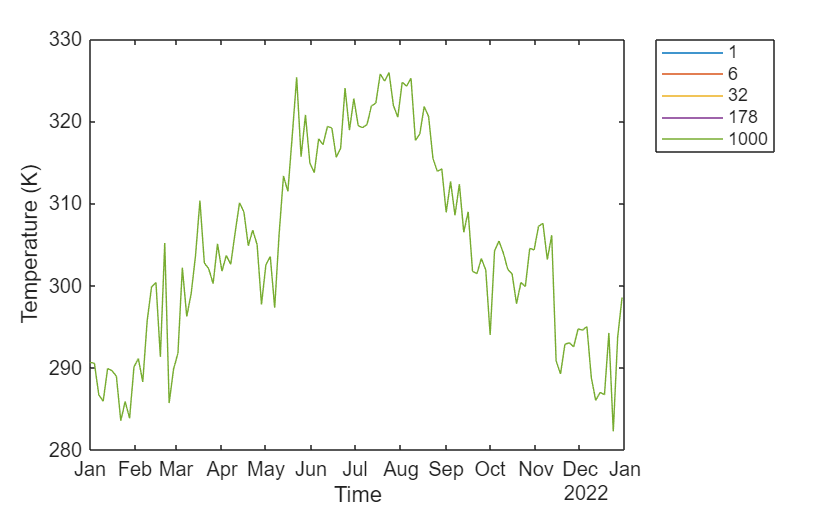

 
figure
for i = 1:numFan
    load_system(fullfile("InstructorResources","Solutions","GreenhousePlantWithControlSoln.slx"))
    set_param("GreenhousePlantWithControlSoln/CFM","value",num2str(CFM(i)))
    SimOut = sim("GreenhousePlantWithControl");
    SimOut = FormatSimOut(SimOut);
    plot(SimOut,"Time","Temperature (K)",DisplayName=num2str(CFM(i)))
    hold on
end
hold off
legend(Location="bestoutside")

Comparing the fans' performance over a full year is not evident. We are trying to control the temperature in the greenhouse over the warmest month of the year.

  **Try.** Use the drop-down list below to limit the data to the summer months.

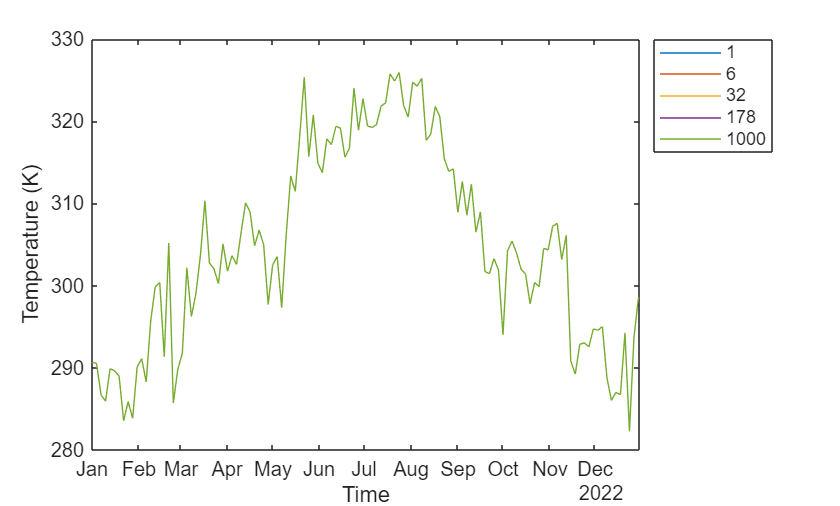

startdate =  "January";
enddate =  "December";
enddate  = datetime(enddate+" 1, 2022");
[y,m,d] = ymd(enddate);
xlim([datetime(startdate+" 1, 2022") datetime(y,m,eomday(y,m))])

 **Reflect. **Why does the fan's size limit the temperature during the hottest day of the year?

## Conclusion

The cooling of the greenhouse is based on using a fan to bring cooler air from the outside of the greenhouse inside. This type of cooling will never be able to cool the greenhouse below the outdoor temperature. During the hottest days of the year, it might be more interesting to open the greenhouse and let the air flow freely instead of using electricity, which consumes electricity.

## Further exploration

In [ConnectectGreenhouse](matlab:open('./GreenhouseControl.mlx')), you can learn how to connect your greenhouse to the internet to monitor the temperature. Moreover, the system can send an alert when the temperature exceeds a certain threshold and notify the user to open the greenhouse.

To learn more about thermal modeling, check out our [Thermodynamic](https://www.mathworks.com/matlabcentral/fileexchange/126784-thermodynamics?s_tid=srchtitle) module, where you can build your refrigerator.

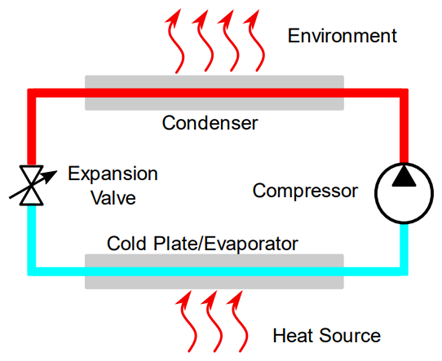

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

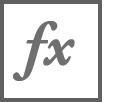`CheckThermalMass`

function CheckThermalMass()
    load_system("GreenhousePlantSoln");
    MassString = string(get_param('GreenhousePlantSoln/Inside','Mass'));
    MassString = str2sym(MassString);
    err = false;
    GoodAnswer = str2sym("Density*(height*Length*Length)");
    isRight = isequal(GoodAnswer,MassString);
    
    if MassString == "Density*(height*Length)"
        err = true;
        warning("Please modify the mass parameter in the Inside block.")
    end
    
    if isRight 
        disp("Good job! You entered the right value in the mass parameter of the Inside block.")
    else
        if ~err
            warning("The parameter you entered in the Inside block is wrong.")
        end
    end
end

`CheckSolver`

function CheckSolver()
    load_system("GreenhousePlantSoln")
    connectivity = get_param("GreenhousePlantSoln/Solver",'PortConnectivity');
    if isempty(connectivity.DstBlock)
        warning("The solver is not connected.")
    else
        disp("Good job! You connected the solver correctly.")
    end
end

`CheckUncommentSensor`

function CheckUncommentSensor()
    load_system("GreenhousePlantSoln");
    c1 = string(get_param("GreenhousePlantSoln/Scope","Commented"));
    c2 = string(get_param("GreenhousePlantSoln/PS-Simulink Converter","Commented"));
    c3 = string(get_param("GreenhousePlantSoln/Temperature Sensor","Commented"));
    err = false;
    if c1 ~= "off"
        err = true;
        warning("The Scope in the sensor area is still commented.")
    end
    if c2 ~= "off"
        err = true;
        warning("The PS-Simulink Converter in the sensor area is still commented.")
    end
    if c3 ~= "off"
        err = true;
        warning("The Sensor in the sensor area is still commented.")
    end
    if ~err
        disp("Good job! You uncommented the sensor blocks correctly.")
    end
end

`CheckExperimentPlan`

function CheckExperimentPlan(minCFM,maxCFM,numFan)
    err = false;
    if minCFM < 0.1
        err = true;
        warning("You should not try for fan below 0.1 CFM.")
    end
    if minCFM > 10
        err = true;
        warning("Your smaller fan should have a rating below 10 CFM.")
    end
    if maxCFM < minCFM
        err = true;
        warning("The maximum CFM should be larger than the minimum CFM.")
    end
    if maxCFM < 1000
        err = true;
        warning("It is reasonable to test for fan all the way up to 1000 CFM.")
    end
    if numFan < 5
        err = true;
        warning("You should at least try 5 fans.")
    end
    if numFan >= 20
        err = true;
        warning("Trying more than 20 fans might take too long, reduce the number of fan you want to test.")
    end

    if ~err
        disp("Good job! You define a reasonable experiment plan.")
    end
end

`FormatSimOut`

function y = FormatSimOut(SimOut)
    SimOut = timeseries2timetable(SimOut.logsout{1}.Values);
    SimOut.Properties.VariableNames(1) = "Temperature (K)";
    SimOut.Time = datetime("Jan 1, 2022") + SimOut.Time;
    SimOut.("Temperature (F)") = 9/5*SimOut.("Temperature (K)")-459.67;
    SimOut.("Temperature (C)") = SimOut.("Temperature (K)")-273.15;
    y = retime(SimOut,"regular","max","TimeStep",caldays(3));
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc